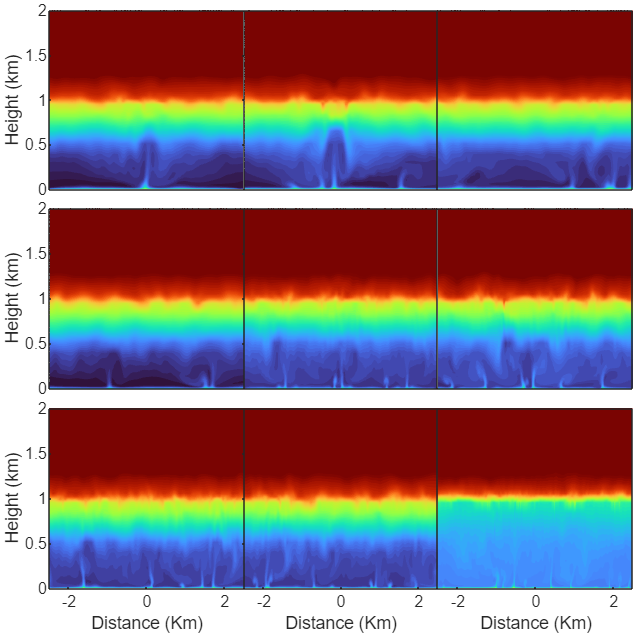

clear all; close all; clc  %Declaraciones preeliminares
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';

% Crear layout
tt = tiledlayout(3, 3, 'TileSpacing', 'tight', 'Padding', 'none');
set(gcf, 'Position', [100, 100, 500, 500]); % Aumentar el tamaño de la figura
for rrr=1:1:9
    switch rrr
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);      
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            yt='#EDB120';
            for i=1:1:6
            un(:,:,12)=[];
            t(:,:,12)=[];
            end
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            yt='#4DBEEE';
            for i=1:1:3
            un(:,:,36)=[];
            t(:,:,36)=[];
            end
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='k';
        case 9
            Ar1=['9'];
            Ar2=['9_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            yt='c';
        case 10
            Ar1=['10'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='m';    
        otherwise 
            Ar1=['11'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    % ejex2=(-dis:dx:dis)/1000;            %En metros 
    gravedad=1.352;
    timebar=1:1:time;
    %  timebar=timebar.*10;
    ftv=0;                           %Temperatura virtual 1 si, 0 no;
    G=5;  %Numero de niveles
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    zi=400;     %Altura de la capa limite convectiva
    % lim=1.25;      %Hasta donde se grafica
    lim=2000;
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:(length(un(:,1,1))-1) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end

    cf= 12;
    xl=[-2.5 2.5];
    yl=[0 2];
    cl=[83.2, 83.4];
switch rrr
        case 1
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ylabel('Height (km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.YAxis.FontSize = cf;  % Cambia el tamaño de los números del eje y
            set(ax, 'XTick', [])
       case 2
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ax = gca;
            set(ax, 'XTick', [], 'YTick', [])
       case 3
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ax = gca;
            set(ax, 'XTick', [], 'YTick', [])
        case 4
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ylabel('Height (km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.YAxis.FontSize = cf;  % Cambia el tamaño de los números del eje y
            set(ax, 'XTick', [])
       case 5
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ax = gca;
            set(ax, 'XTick', [], 'YTick', [])
       case 6
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ax = gca;
            set(ax, 'XTick', [], 'YTick', [])
        case 7
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ylabel('Height (km)')
            xlabel('Distance (Km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.YAxis.FontSize = cf;  % Cambia el tamaño de los números del eje y
            ax.XAxis.FontSize = cf;  % Cambia el tamaño de los números del eje X    
        case 8
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            xlabel('Distance (Km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.XAxis.FontSize = cf;  % Cambia el tamaño de los números del eje X 
            set(ax, 'YTick', [])
        case 9
            nexttile
            contourf(ejex1,ejez./1000,t(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            xlabel('Distance (Km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.XAxis.FontSize = cf;  % Cambia el tamaño de los números del eje X 
            set(ax, 'YTick', [])
end
clear u un t 
end 
% tt.InnerPosition = [0.05 0.05 0.9 0.9];
print('Figura2A', '-dpng', '-r1000');

clear all; close all; clc  %Declaraciones preeliminares
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';

% Crear layout
tt = tiledlayout(3, 3, 'TileSpacing', 'tight', 'Padding', 'none');
set(gcf, 'Position', [100, 100, 500, 500]); % Aumentar el tamaño de la figura
for rrr=1:1:9
    switch rrr
        case 1
            Ar1=['1'];
            time=49;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=126;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
        case 2
            Ar1=['2'];                      %Nombre del Archivo
            Ar2=['2_2'];
            time=78;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=251;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);      
        case 3
            Ar1=['3'];                      %Nombre del Archivo
            Ar2=['3_2'];
            time=53;                             %Hora
            dx=40;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            yt='#EDB120';
            for i=1:1:6
            un(:,:,12)=[];
            t(:,:,12)=[];
            end
        case 4
            Ar1=['4'];
            time=50;   
            dx=40;                        
            puntosx=1001;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='#7E2F8E';
        case 5 
            Ar1=['5'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=251;
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='#77AC30';
        case 6
            Ar1=['6'];
            Ar2=['6_2'];
            time=59;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=501; 
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            yt='#4DBEEE';
            for i=1:1:3
            un(:,:,36)=[];
            t(:,:,36)=[];
            end
        case 7
            Ar1=['7'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=1001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='#A2142F';
        case 8
            Ar1=['8'];
            time=49;                             %Hora
            dx=20;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='k';
        case 9
            Ar1=['9'];
            Ar2=['9_2'];
            time=50;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=501;  
            un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
            t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
            yt='c';
        case 10
            Ar1=['10'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=2001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='m';    
        otherwise 
            Ar1=['11'];
            time=72;                             %Hora
            dx=10;                                %Grosor de la malla
            puntosx=4001; 
            un = squeeze(ncread(Ar1,Var1));
            t = squeeze(ncread(Ar1,Var2))+100;
            yt='--';
    end
    puntosz=99;                           %Tamaño Vertical de malla
    dis=(puntosx-1)*dx/2;                     %Limite horizontal
    ejex1=((-dis):dx:(dis))/1000;              %En metros
    clear dis
    ejex2=ejex1;
    ejex1(length(ejex1))=[];
    % ejex2=(-dis:dx:dis)/1000;            %En metros 
    gravedad=1.352;
    timebar=1:1:time;
    %  timebar=timebar.*10;
    ftv=0;                           %Temperatura virtual 1 si, 0 no;
    G=5;  %Numero de niveles
    %Primero, cree niveles verticales geométricos a partir del geopotencial:
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    zi=400;     %Altura de la capa limite convectiva
    % lim=1.25;      %Hasta donde se grafica
    lim=2000;
    ejez2=mean(gz2d)./(gravedad);
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    clear gz2d gz
    %%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
        
    %Leemos la variable a visualizar

    for i=1:1:(length(un(:,1,1))-1) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end

    cf= 12;
    xl=[-2.5 2.5];
    yl=[0 2];
    cl=[-0.5, 0.5];
switch rrr
        case 1
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ylabel('Height (km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.YAxis.FontSize = cf;  % Cambia el tamaño de los números del eje y
            set(ax, 'XTick', [])
       case 2
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ax = gca;
            set(ax, 'XTick', [], 'YTick', [])
       case 3
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ax = gca;
            set(ax, 'XTick', [], 'YTick', [])
        case 4
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ylabel('Height (km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.YAxis.FontSize = cf;  % Cambia el tamaño de los números del eje y
            set(ax, 'XTick', [])
       case 5
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ax = gca;
            set(ax, 'XTick', [], 'YTick', [])
       case 6
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ax = gca;
            set(ax, 'XTick', [], 'YTick', [])
        case 7
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            ylabel('Height (km)')
            xlabel('Distance (Km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.YAxis.FontSize = cf;  % Cambia el tamaño de los números del eje y
            ax.XAxis.FontSize = cf;  % Cambia el tamaño de los números del eje X    
        case 8
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            xlabel('Distance (Km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.XAxis.FontSize = cf;  % Cambia el tamaño de los números del eje X 
            set(ax, 'YTick', [])
        case 9
            nexttile
            contourf(ejex1,ejez./1000,u(:,:,24)',500,'EdgeColor','none')
            colormap(turbo), % colorbar
            xlim(xl)
            ylim(yl)
            clim(cl)
            xlabel('Distance (Km)')
            ax = gca;  % Obtiene el objeto de los ejes actuales
            ax.XAxis.FontSize = cf;  % Cambia el tamaño de los números del eje X 
            set(ax, 'YTick', [])
end
clear u un t 
end 
% tt.InnerPosition = [0.05 0.05 0.9 0.9];
print('Figura2B', '-dpng', '-r1000');